## Problem 2

Consider two independent Poisson random variables $X$ and $Y$ , with parameters $\lambda_X := 3$ and $\lambda_Y := 4$. 

lmd_x=3;
lmd_y=4;

- Define a random variable $Z := X + Y$ , having a probability mass function (PMF) $P(Z)$. 

 (i) Empirically obtain an estimate $\hat{P}(Z)$ of the PMF $P(Z)$, by drawing $N = 10^6$ instances (sample points) of $X$ and $Y$ both. You may use the poissrnd(.) function in Matlab. Report the values of $\hat{P}(Z = k)$ for $k = 0, 1, 2, \cdots , 25$. 

N=10^6; 
% Z = X + Y we do for all instances together
Z_1 = poissrnd(lmd_x,N,1)+poissrnd(lmd_y,N,1)

Z_1 =      8
    14
    12
    14
     7
     4
     9
     5
     4
     5


P_emp_1 = hist(Z,(0:25));
P_emp_1 = P_emp_1 / sum(P_emp_1)

P_emp_1 =     0.0009    0.0065    0.0228    0.0523    0.0919    0.1282    0.1488    0.1482    0.1300    0.1014    0.0707    0.0450    0.0266    0.0142    0.0071    0.0033    0.0014    0.0006    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0


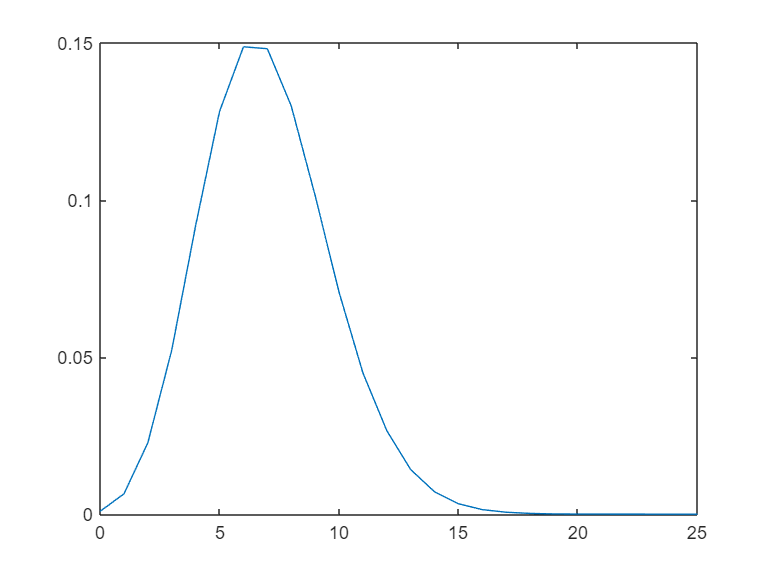

plot((0:25),P_emp_1)

(ii) What will the PMF $P(Z)$ be theoretically/analytically ? 

The poisson distribution is


$$P_\lambda(a) = \frac{\lambda^a}{a!} e^{-\lambda}$$


$P(Z=z)$ is


$$P(Z=z) = \sum_{x=0}^z P(X=x)\cdot P(Y=z-x)$$



$$= \sum_{x=0}^z \frac{\lambda_x^x}{x!}\frac{\lambda_y^{z-x}}{(z-x)!} e^{-\lambda_x -\lambda_y}$$



$$= \sum_{x=0}^z \frac{(\lambda_x/\lambda_y)^x \cdot{ }^zC_x}{z! } \lambda_y^z e^{-\lambda_x -\lambda_y}$$



$$= \frac{(\lambda_x+\lambda_y)^z}{z!} e^{-(\lambda_x+\lambda_y)}$$


This is a new poisson distribution.

(iii) Show and compare the values for $\hat{P}(Z = k)$ and $P(Z = k)$ for $k = 0, 1, 2, \cdots , 25$.

P_th_1 = zeros(25,1);
for i=(0:25)
    P_th_1(i+1) = (lmd_x+lmd_y)^i * exp(-lmd_x-lmd_y) /factorial(i);
end

disp(P_th_1);

    0.0009
    0.0064
    0.0223
    0.0521
    0.0912
    0.1277
    0.1490
    0.1490
    0.1304
    0.1014
    0.0710
    0.0452
    0.0263
    0.0142
    0.0071
    0.0033
    0.0014
    0.0006
    0.0002
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



disp(P_emp_1);

  Columns 1 through 10

    0.0009    0.0065    0.0228    0.0523    0.0919    0.1282    0.1488    0.1482    0.1300    0.1014

  Columns 11 through 20

    0.0707    0.0450    0.0266    0.0142    0.0071    0.0033    0.0014    0.0006    0.0002    0.0001

  Columns 21 through 26

    0.0000    0.0000    0.0000    0.0000    0.0000         0



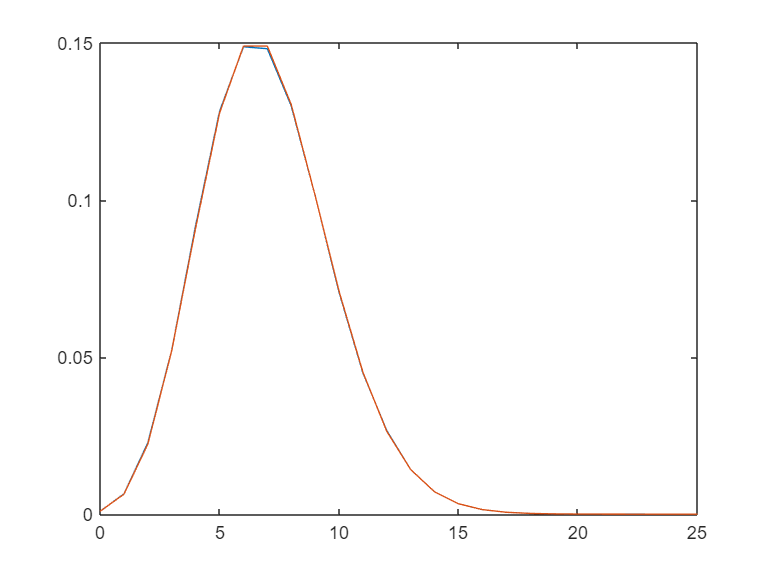

plot((0:25),P_emp_1); %add labels n shit
hold on;
plot((0:25),P_th_1);
hold off;

- Implement a Poisson thinning process (as discussed in class) on the random variable Y , where the thinning process uses probability parameter 0.8. Let the thinned random variable be Z.  

(i) Empirically obtain an estimate $\hat{P}(Z)$ of the PMF $P(Z)$, by drawing $N := 10^5$ instances (sample points) from $Y$ . You may use the poissrnd(.) and binornd(.) functions in Matlab. Report the values of $\hat{P}(Z = k)$ for $k = 0, 1, 2, \cdots , 25$. 

N=10^5;
p=0.8;
Y_2= poissrnd(lmd_y,N,1)

Y_2 =      0
     5
    10
    10
     6
     6
     2
     3
     5
     3


Z_2=binornd(yarr,p)

Z_2 =      4
     6
     6
     1
     3
     5
     3
     2
     1
     4


P_emp_2 = hist(Z_2,(0:25));
P_emp_2 = P_emp_2 /sum(P_emp_2)

P_emp_2 =     0.0403    0.1296    0.2091    0.2207    0.1780    0.1151    0.0620    0.0282    0.0107    0.0043    0.0014    0.0004    0.0002    0.0000         0         0         0         0         0         0         0         0         0         0         0         0


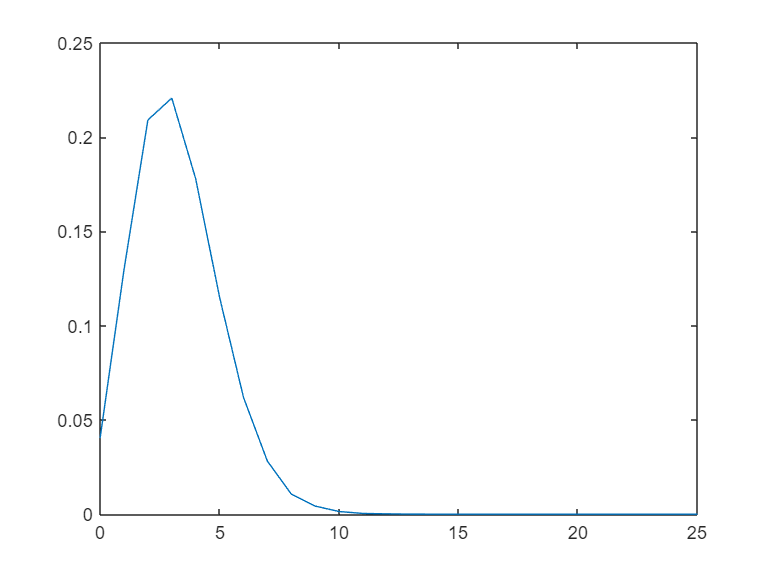

plot((0:25),P_emp_2)

(ii) What will the PMF $P(Z)$ be theoretically/analytically ? 

refer slides and fill here


$$= \frac{e^{-\lambda p}(\lambda p)^k}{k!}$$


(iii) Show and compare the values for $\hat{P}(Z = k)$ and $P(Z = k)$ for $k = 0, 1, 2, \cdots , 25$.

P_th_2 = zeros(25,1);
for i=(0:25)
    P_th_2(i+1) = (lmd_y*p)^i * exp(-lmd_y*p) /factorial(i);
end
disp(P_th_2);

    0.0408
    0.1304
    0.2087
    0.2226
    0.1781
    0.1140
    0.0608
    0.0278
    0.0111
    0.0040
    0.0013
    0.0004
    0.0001
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000



disp(P_emp_2);

  Columns 1 through 10

    0.0403    0.1296    0.2091    0.2207    0.1780    0.1151    0.0620    0.0282    0.0107    0.0043

  Columns 11 through 20

    0.0014    0.0004    0.0002    0.0000         0         0         0         0         0         0

  Columns 21 through 26

         0         0         0         0         0         0



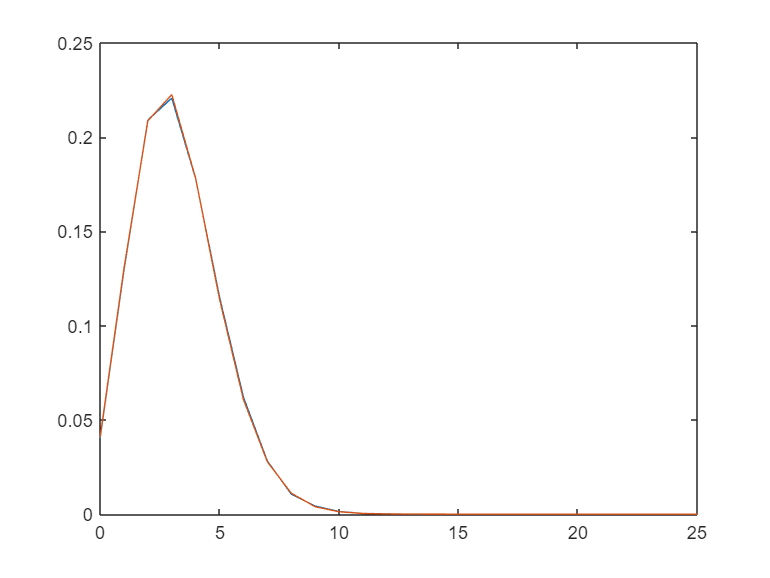

plot((0:25),P_emp_2); %add labels n shit
hold on;
plot((0:25),P_th_2);
hold off;